# Simul 4H and experimental data

#### Ver 3-22b

Copyright (C) 2022  Enrique Cárdenas-Sanchez.

  email: enricardenass@gmail.com

Matlab 2022B 

This program is free software; you can redistribute it and/or modify it under the terms of the GNU General Public License as published by the Free Software Foundation; either version 2 of the License, or (at your option) any later version.

This program is distributed in the hope that it will be useful,

but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details.

You should have received a copy of the GNU General Public License along with this program; if not, write to the Free Software

Foundation, Inc., 59 Temple Place, Suite 330, Boston, MA  02111-1307  USA


clear all
close all

cd("C:\Users\ekrde\Desktop\data")
xxa=6;
xxb=1;
[data,sname]=data_file_2(xxa,xxb)

sdataname = 1×7 cell array
    {'r6cm400C'}    {'r6cm600C'}    {'r6cm700C'}    {'r6cm800C'}    {'r6cm500CE2f'}    {'r6cm600CE2B'}    {'r6cm600CE2f'}


data =    18.0000    3.0000   55.0000  383.8000  374.0000  315.6000   28.6000
   18.0000    3.0000   57.0000  383.9000  374.0000  315.3000   28.5000
   18.0000    3.0000   59.0000  384.0000  374.1000  315.0000   28.5000
   18.0000    4.0000    1.0000  384.0000  374.2000  314.7000   28.4000
   18.0000    4.0000    3.0000  384.1000  374.2000  314.6000   28.4000
   18.0000    4.0000    5.0000  384.2000  374.3000  314.3000   28.4000
   18.0000    4.0000    7.0000  384.3000  374.3000  314.0000   28.3000
   18.0000    4.0000    9.0000  384.3000  374.3000  313.7000   28.3000
   18.0000    4.0000   11.0000  384.4000  374.4000  313.4000   28.2000
   18.0000    4.0000   13.0000  384.4000  374.4000  313.1000   28.2000


sname = 'r6cm400C'



%%%%%%%%%% Modelo lineal %%%%%%
cc=2;
ccmax=1;

kkData=zeros(cc,ccmax);
ERRORES=zeros(5,ccmax);
ERRORES2=zeros(5,ccmax);
K2=zeros(1,4);
kk=zeros(cc,1);

% from thesis and paper for 3 samples
if xxa==6
    rho= 2202.4;
elseif xxa==8
    rho=2243.2;
elseif xxa==10
    rho = 1740.2;
end

tmm=(data(:,1)-data(1,1))*3600+(data(:,2)-data(1,2))*60+data(:,3)-data(1,3); % cambio de formato de tiempo a segundos.
Temperature_data=data(:,4:6)+273.5;

[T_max,aa]=max(max(Temperature_data))

T_max = 659.7000

aa = 1

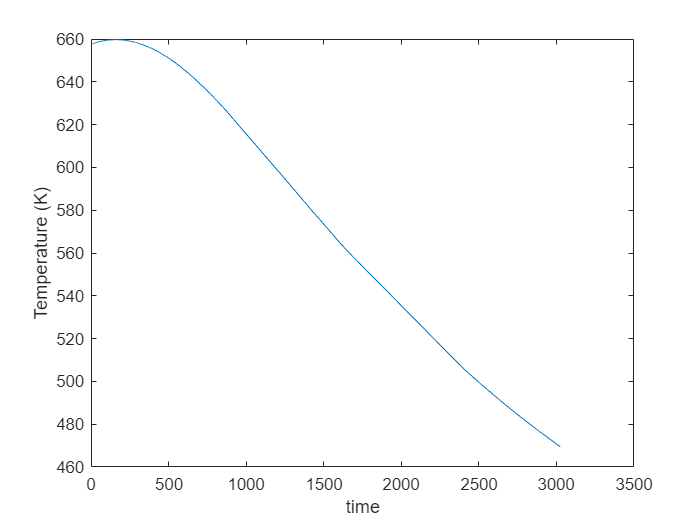


plot(tmm,Temperature_data(:,aa))
xlabel('time')
ylabel('Temperature (K)')

tic 
t=tmm;
t_grid=round(max(t)/60)

t_grid = 50


LL1=length(t);
data_input=[t,Temperature_data(:,aa)];%vec=2:50:LL1;
vec=round(linspace(1,LL1,t_grid));
t(vec)

ans =      0
    36
    74
   110
   148
   184
   222
   258
   296
   332


Tdata=Temperature_data(:,aa);

LL2=length(vec)

LL2 = 50


%H_in=0.025
a_size=xxa*.01

a_size = 0.0600

 
for ii=1:LL2-1
 Tin=(Tdata(vec(ii+1))+Tdata(vec(ii)))/2;
   t0=t(vec(ii+1));
    H_0=0.001;
    seed=[Tin,t0,H_0,0.6];
[H_Best, Error, Tmodel_Best]=SimulatedAnealing_SimuH(seed);
Saving_data(ii,:)=[H_Best, Error, Tmodel_Best];
timer(ii)=t0;
end
toc

Elapsed time is 18.201728 seconds.


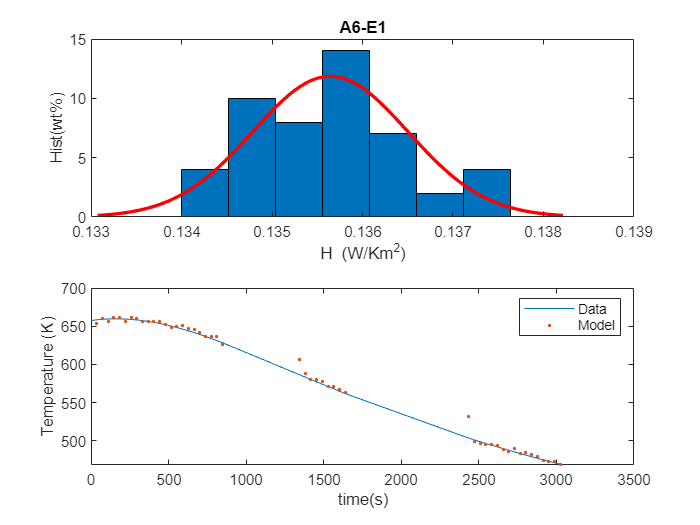


H_model= Saving_data(:,1);
Errors= Saving_data(:,2);
T_model= Saving_data(:,3);
figure
subplot(2,1,1)
histfit(H_model)
xlabel("H (W/Km^2)")
ylabel("Hist(wt%)")
title("A6-E1")
subplot(2,1,2)
plot(t(vec),Tdata(vec))
hold on
plot(timer,T_model,'.')
xlabel("time(s)")
ylabel("Temperature (K)")
legend("Data","Model")

Stat_H=[mean(H_model), std(H_model), mean(Errors)]

Stat_H =     0.1356    0.0009    0.0076



snfile=strcat(sname,"-stats_H.txt")

snfile = "r6cm400C-stats_H.txt"

cd('C:\Users\ekrde\Desktop\data log\save_data')
save(snfile,'Stat_H','-ascii')
snfile2=strcat(sname,"-plot.svg")

snfile2 = "r6cm400C-plot.svg"

print(snfile2,'-dsvg')

cd ..

hold off

cd('C:\Users\ekrde\Desktop\data log\save_data\newgraf')

vec2=vec(2:end)

vec2 =     19    38    56    75    93   112   130   149   167   185   204   222   241   259   278   296   315   333   352   370   388   407   425   444   462   481   499   518   536   554   573   591   610   628   647   665   684   702   721   739   757   776   794   813   831   850   868   887   905


Tdata(vec2)

ans =   658.4000
  659.1000
  659.5000
  659.7000
  659.6000
  659.4000
  658.9000
  658.2000
  657.4000
  656.3000


err=Tdata(vec2)-T_model;

figure(4)
 plot(t(vec),Tdata(vec))
 hold on
errorbar(timer,T_model,err,'.')
xlabel("time(s)")
ylabel("Temperature (K)")
legend("Data","Model")
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
title("A6-E1: Data vs Model")
snfile3=strcat("A6E1","-DatavsMode_2.svg")

snfile3 = "A6E1-DatavsMode_2.svg"

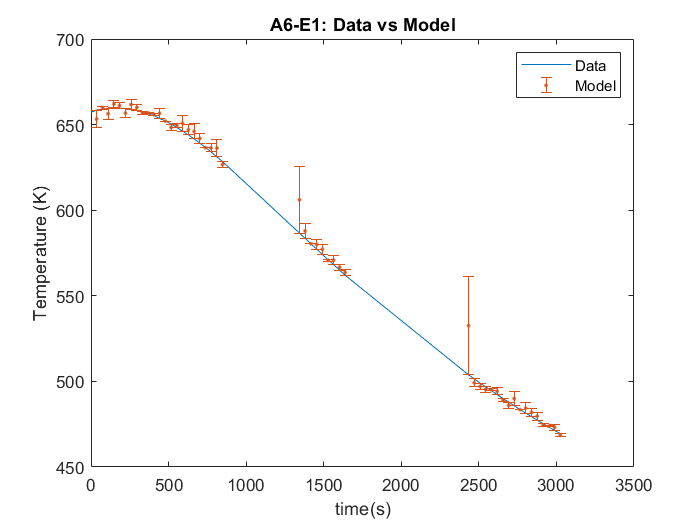

print(snfile3,'-dsvg')
hold off


figure(5)
histfit(H_model,7)
xlabel("H (W/Km^2)")
ylabel("Hist(wt%)")
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
title("A6-E1: Histogram")
snfile4=strcat("A6E1","-Hhisto_2.svg")

snfile4 = "A6E1-Hhisto_2.svg"

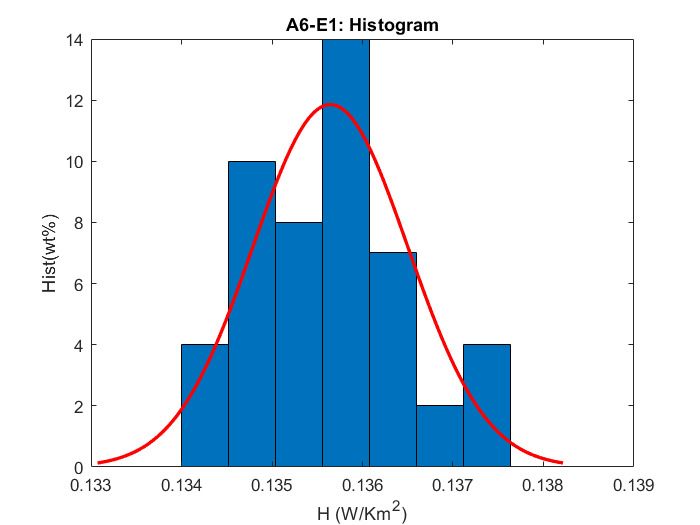

print(snfile4,'-dsvg')


cd('C:\Users\ekrde\Desktop\data log')



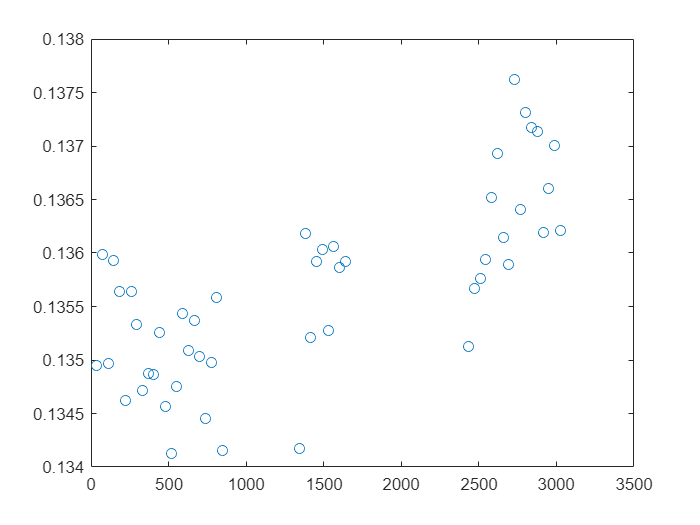

figure
plot(timer,H_model,'o')